# Supplementary figure 2: Dependency of statistics on the value of P and D

Global statistcs as average and variance, spatial statistics as mean curve with 95% CI and variance of noise

### Figure A: Statistcs for P = D = 0.1

Exp: 9-6

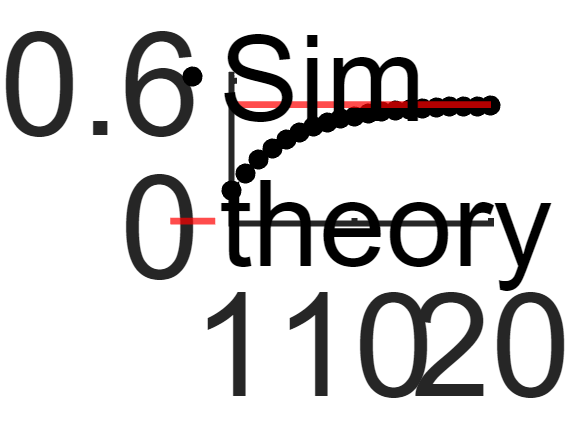

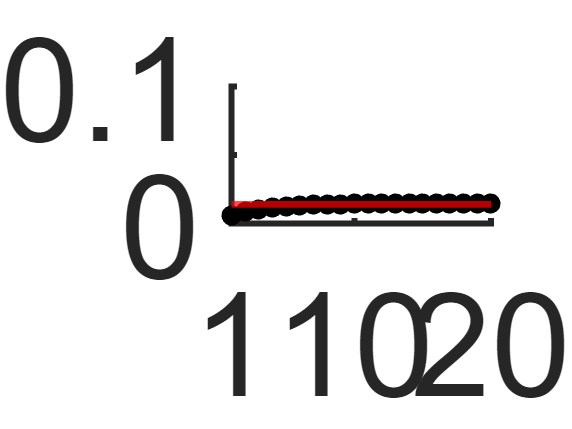

clear; clc
load(fullfile(read_output_dir(), "SupFig2/PDdot1.mat"))


n = 20;     legend_on = true; is_stack = false;
plot_mean_variance(n, weight_mean, weight_var, P, D, legend_on)

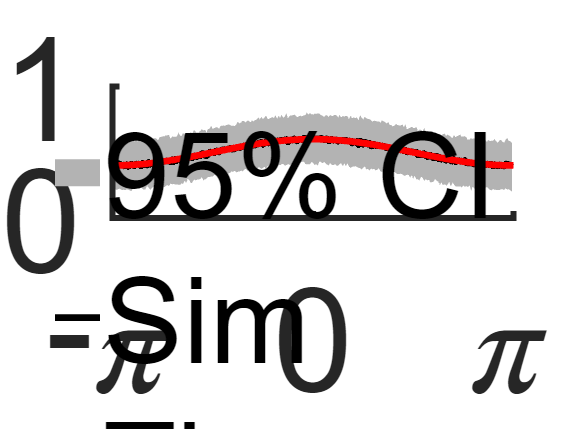

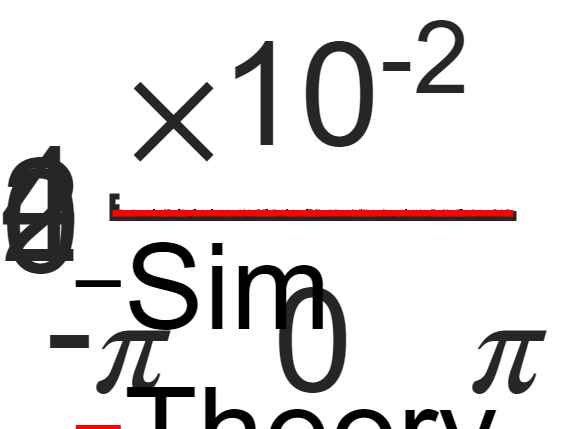

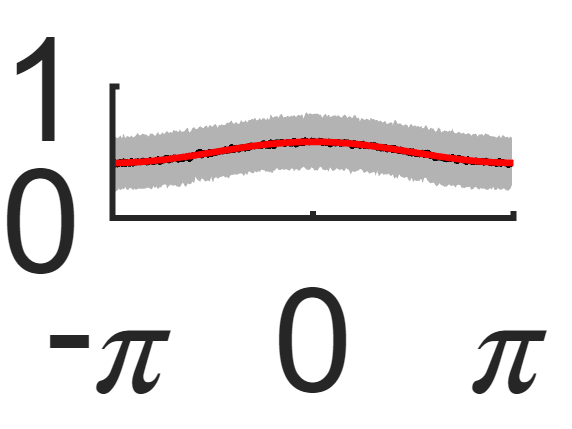

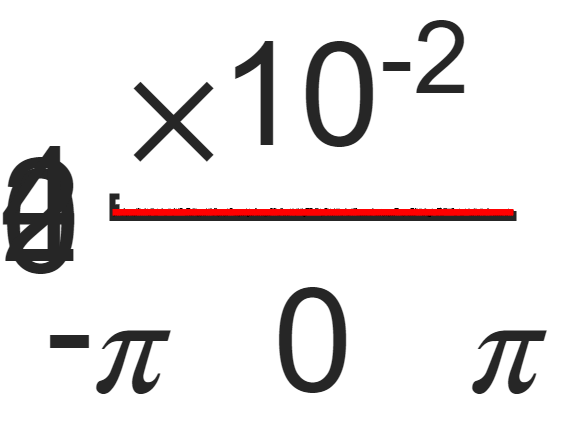

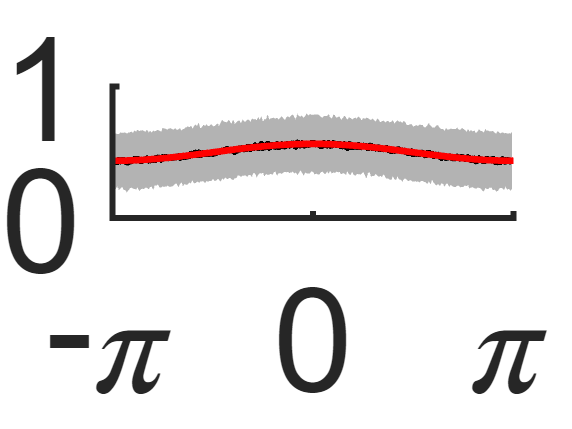

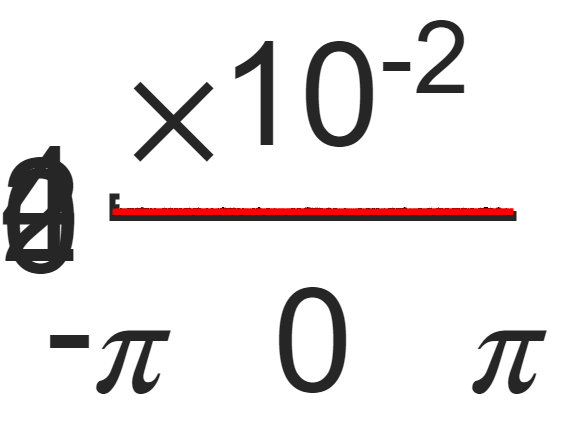

plot_mean_variance_curve(final_weight, Env_track, n_ca3_per_track, phase, ...
    P, D, M, s, legend_on)

### Figure B: Statistcs for P = 0.1 and D= 0.3

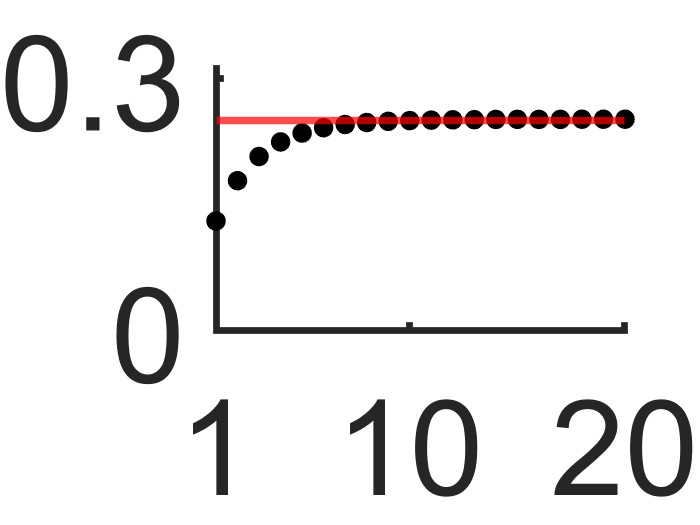

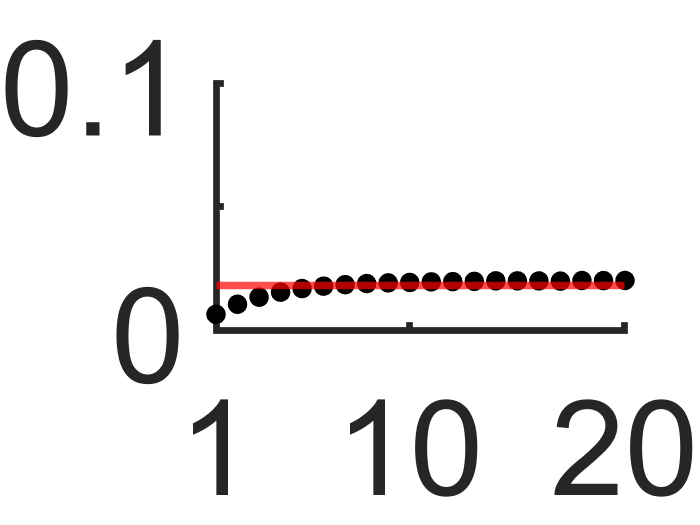

clear; clc;
load(fullfile(read_output_dir(), "SupFig2/Pdot1Ddot3.mat"))
n = 20;     legend_on = false; is_stack = false;
plot_mean_variance(n, weight_mean, weight_var, P, D, legend_on)

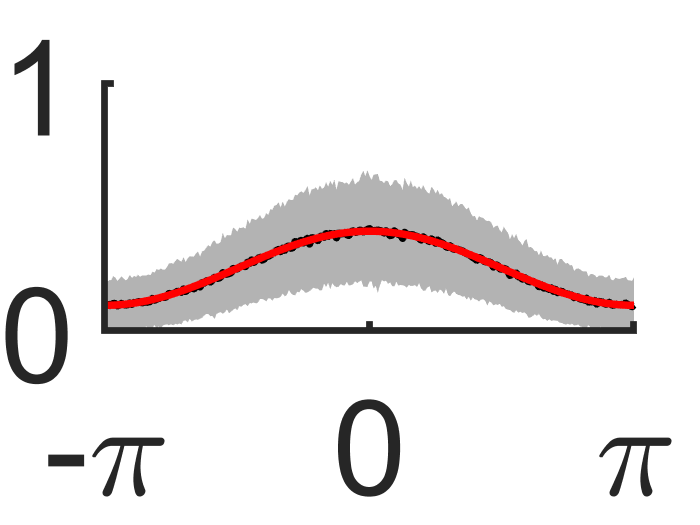

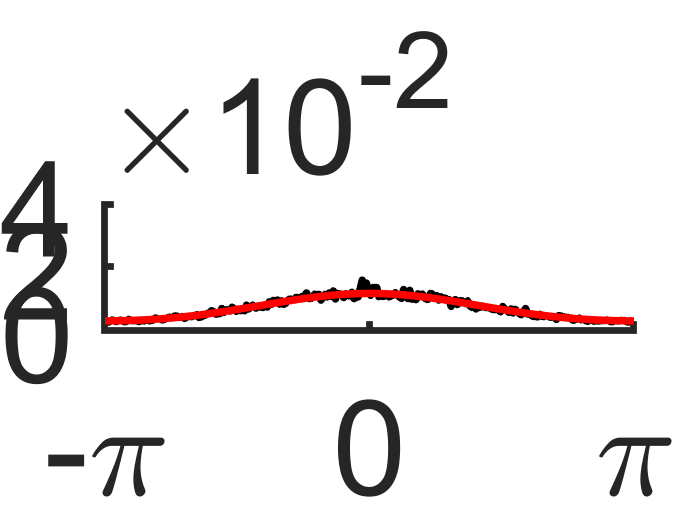

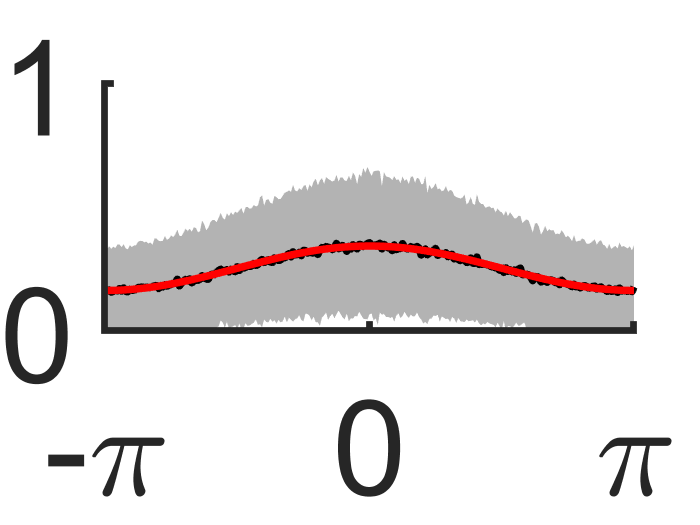

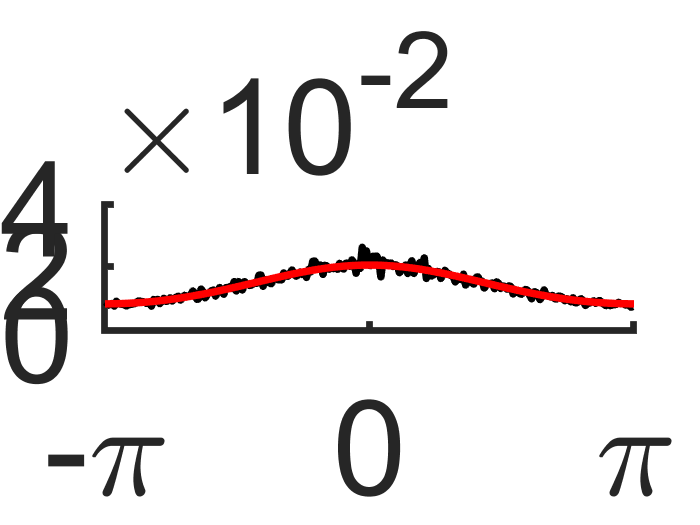

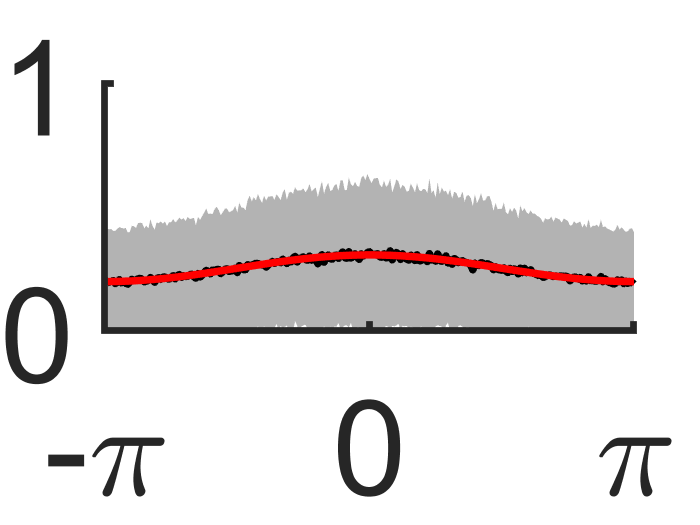

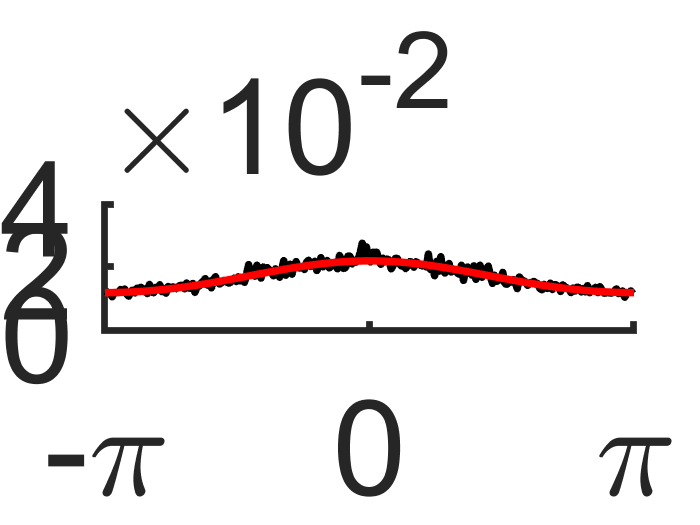

plot_mean_variance_curve(final_weight, Env_track, n_ca3_per_track, phase, ...
    P, D, M, s, legend_on)

### Figure C: Statistcs for P = 0.3 and D = 0.1

clear; clc;

load(fullfile(read_output_dir(), "SupFig2/Pdot3Ddot1.mat"))
n = 20;     legend_on = false; 
plot_mean_variance(n, weight_mean, weight_var, P, D, legend_on)
plot_mean_variance_curve(final_weight, Env_track, n_ca3_per_track, phase, ...
    P, D, M, s, legend_on)

## Auxiliar functions

function plot_mean_variance(n, weight_mean, weight_var, P, D, legend_on)
    figure
    plot(1:n, weight_mean(1:n), ".k", "MarkerSize", 40)
    theoretical_mean = P/(P+D);
    yline(theoretical_mean, "-r", "LineWidth", 4.5)
    ylim([0, theoretical_mean*1.25])
    yticks([0, floor(theoretical_mean*1.25 *10)/10])
    xlim([1, n])
    aux = 10:10:n;
    aux = [1, aux];
    xticks(aux)
    box off
    if legend_on
        legend(["Sim", "theory"], "Location","best")
        legend boxoff
    end
    fig_config(80)
    
    figure
    plot(1:n, weight_var(1:n), ".k", "MarkerSize", 40)
    theoretical_var = 2 * P^2 * D^2 / (P+D)^2 / (2 * (P*D + P + D) - 3/2 * (P+D)^2);
    yline(theoretical_var, "r", "LineWidth", 4.5)
    ylim([0, theoretical_var *1.25])
    
    ylim([0, 0.1])
    yticks([0, 0.05, 0.1])
    yticklabels([0, "", 0.1])
    %ax=gca; ax.YAxis.Exponent = -2;
    %xlabel("Nº Environment (k)")
    xlim([1, n])
    xticks(aux)
    box off
    fig_config(80)
end

function plot_mean_variance_curve(final_weight, Env_track, n_ca3_per_track, phase, ...
    P, D, M, s, legend_on)
    is_stack = false;
    for k = [0, 1, 2]
        rng(1997)
        [theo_mean, theo_var, theo_phase] = Compute_mean_variance(P, D, k, is_stack, M, s);
        [sort_weight_k, phase_modf] = Aligment(final_weight, Env_track, k, phase, n_ca3_per_track, M, s, is_stack);
        mean_weight = mean(sort_weight_k);
    
        % Since the phase for each cell to itself is always 0, then the
        % plasticty rule we defined before only remains the potentiation
        % part because the depression is always 0. 
        % To avoid the ugly representation of weight, we have either delete
        % the autolop point or smooth the autoconnection weight and also
        % the variance. 
        modified_weight = mean_weight;
        ind_logic = abs(phase_modf) < 0.3 & phase_modf ~= 0;
        attach_weight = mean_weight(ind_logic);
        modified_weight(abs(phase_modf) < 0.1) = normrnd(mean(attach_weight), std(attach_weight)/5, 1, length(modified_weight(abs(phase_modf) < 0.1)));

        noise = sort_weight_k - mean_weight;
        var_sim = var(noise);
        attach_var = var_sim(abs(phase_modf) < 0.3 & phase_modf ~= 0);
        var_sim(abs(phase) < 0.1) = normrnd(mean(attach_var), std(attach_var)/5, 1, length(var_sim(abs(phase) < 0.1)));
        
        upper_band = modified_weight + sqrt(var_sim) * 1.96;
        lower_band = modified_weight - sqrt(var_sim) * 1.96;
        figure
        h1 = fill([phase_modf', fliplr(phase_modf')], [upper_band, lower_band], [.7,.7,.7], 'EdgeColor','none', 'FaceAlpha', 1);
        hold on
        plot(phase_modf, modified_weight, "k", "LineWidth", 4.5)
        plot(theo_phase, theo_mean, "r", "LineWidth", 4.5)
        hold off
        box off
        xlim([-pi, pi])
        xticks([-pi, 0, pi])
        xticklabels("")
        xticklabels(["-\pi", 0, "\pi"])
        ylim([0, 1])
        yticks([0, 1])

        if k == 0 & legend_on
            legend("95% CI", "Sim", "Theory", "FontSize", 80*0.7, "location", "northeast");
            legend boxoff
        end
        fig_config(80)
        
        figure
        plot(phase, var_sim, "k", "LineWidth", 4.5)
        hold on
        plot(theo_phase, theo_var, "r", "LineWidth", 4.5)
        hold off
        box off
        xlim([-pi, pi])
        xticks([-pi, 0, pi])
        xticklabels(["-\pi", 0, "\pi"])
        
        aux = mean(var_sim);
        ylim([0, 0.04])
        yticks([0, 0.02, 0.04])
        ax=gca; ax.YAxis.Exponent = -2;
        if k == 0 & legend_on
            legend(["Sim", "Theory"], "Location","northeast")
            legend boxoff
        end
        fig_config(80) 
    end
end